# 测试

clc
clear
close all
addpath("src\");

## C-W交会

n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [2200., 8000., 1000., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
step = 1;
args.n = n;
args.tspan = 1;
args.f = 0.01;

### 双脉冲

[dv, dv0, ~] = Cw2Impulse(n, x0, tf, xf)

dv =     7.6600    4.9969    2.6630


dv0 =     1.4451
   -4.7827
    0.0842


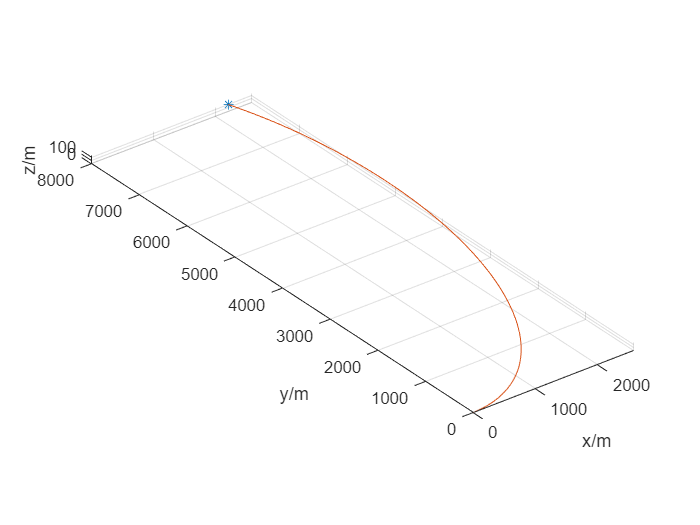

r = x0(1 : 3);
v = x0(4 : 6) + dv0;
[t, x] = ode45(@(t, x) CwEq(t, x, zeros(3, 1), args), 0 : step : tf, [r; v]);
figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

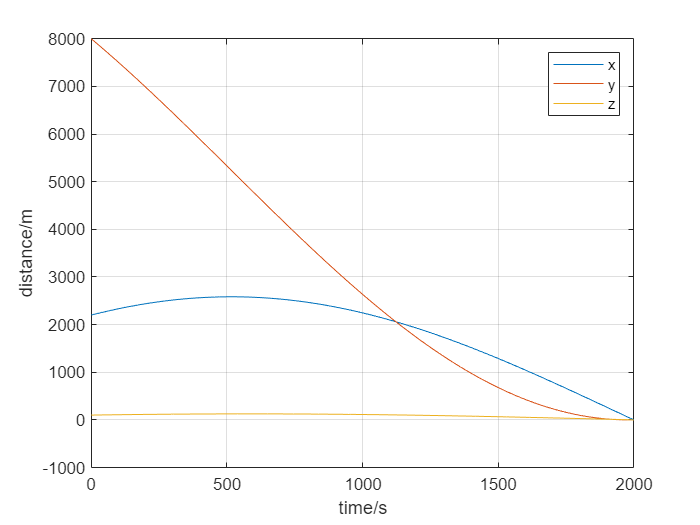

figure
plot(t, x(:, 1 : 3))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')

### 多脉冲转连续推力

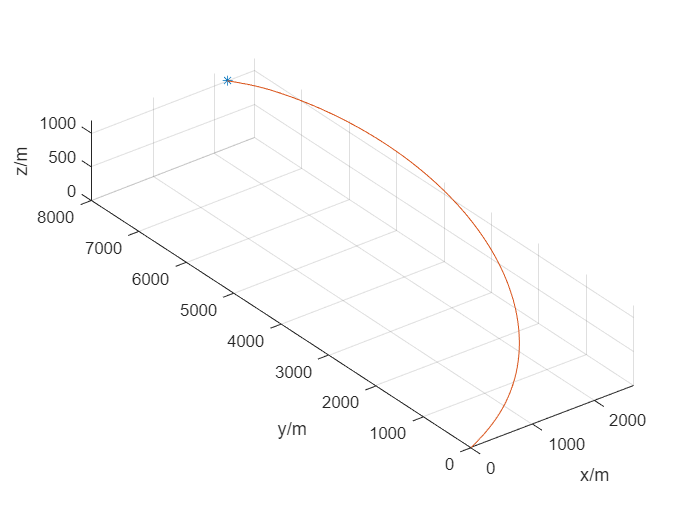

dt = 100;
args.n = n;
t1 = 0;
t2 = tf;
x1 = x0;
x2 = xf;
s0 = [];
sf = [];
for i = 1 : tf / dt / 2
    [~, dv0, dvf] = Cw2Impulse(n, x1, t2(end) - t1(end), x2);
    u0 = dv0 / dt;
    uf = dvf / dt;
    [t1, s1] = ode45(@(t, x) CwEq(t, x, u0, args), t1(end) + (0 : step : dt), x1);
%     plot(t1, s1(:, 1), 'b', t1, s1(:, 2), 'r', t1, s1(:, 3), 'y')
    [t2, s2] = ode45(@(t, x) CwEq(t, x, uf, args), t2(end) - (0 : step : dt), x2);
%     plot(t2, s2(:, 1), 'b', t2, s2(:, 2), 'r', t2, s2(:, 3), 'y')
    x1 = s1(end, :)';
    x2 = s2(end, :)';
    s0 = [s0(1 : end - 1, :); t1, s1, [u0', norm(u0)] .* ones(length(t1), 1)];
    sf = [sf(1 : end - 1, :); t2, s2, [uf', norm(uf)] .* ones(length(t2), 1)];
end
s0 = [s0; flip(sf(1 : end - 1, :))];
figure
plot3(s0(1, 2), s0(1, 3), s0(1, 4), '*')
hold on
plot3(s0(:, 2), s0(:, 3), s0(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

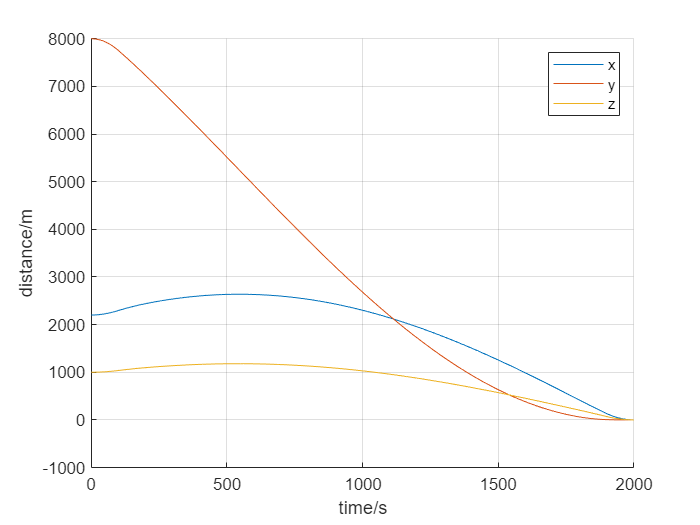

figure
hold on
plot(s0(:, 1), s0(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

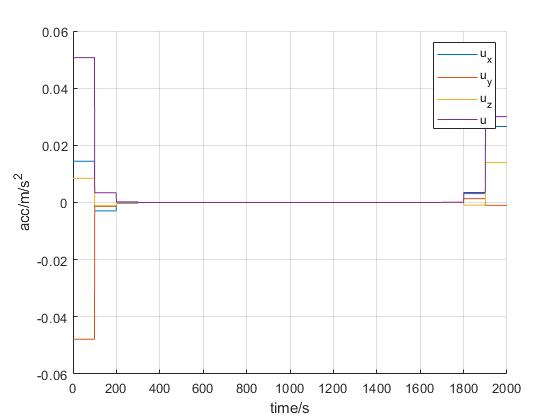

figure
hold on
plot(s0(:, 1), s0(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 高斯伪谱法

args.n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [2200., 8000., 100., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
lb = [-1000, -1000, -100, -10, -10, -1, -0.5, -0.5, -0.1, 0.1 * tf];
ub = [3000, 9000, 200, 10, 10, 1, 0.5, 0.5, 0.1, 1.2 * tf];

#### 时间最优

[s, x_nlp, fval, exitflag, output, lambda, ct] = Gpm(x0, xf, @CostTime, @CwEq, s0, lb, ub, 10, step, args);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      92    2.000000e+03    3.176e+03    9.994e-01
    1     184    1.999959e+03    2.989e+03    1.988e+00    4.157e+00
    2     276    1.999880e+03    2.829e+03    1.988e+00    3.675e+00
    3     368    1.999759e+03    2.675e+03    1.988e+00    3.608e+00
    4     460    1.997616e+03    7.586e+02    1.986e+00    4.536e+01
    5     552    1.997594e+03    7.490e+02    9.745e-01    2.285e-01
    6     644    1.993033e+03    2.807e+02    9.710e-01    2.328e+01
    7     736    1.992999e+03    2.783e+02    8.641e-01    1.209e-01
    8     828    1.999462e+03    1.438e+00    6.744e+00    3.998e+01
    9     920    1.994203e+03    2.734e-01    9.630e+00    1.224e+01
   10    1012    1.990803e+03    3.115e-01    3.489e+00    7.675e+00

fmincon 

ct

ct = 5.0506

tf_ = s(end, 1)

tf_ = 1990

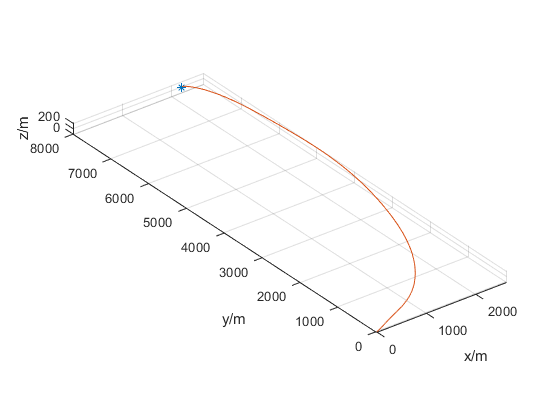

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

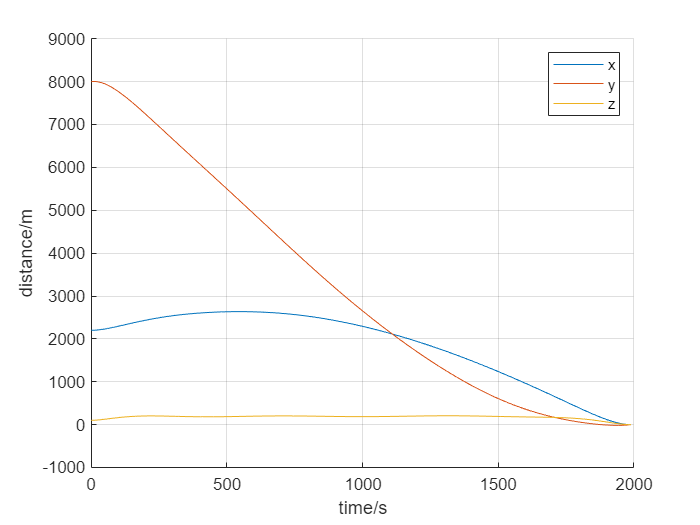

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

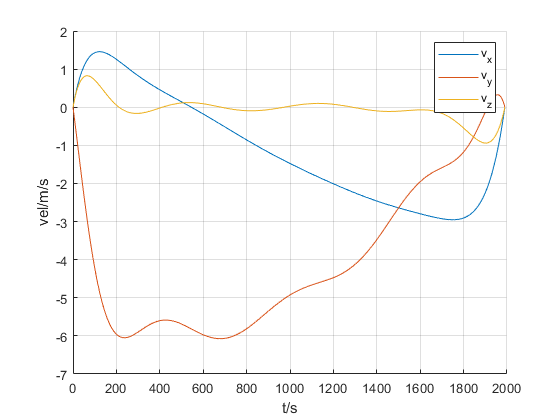

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

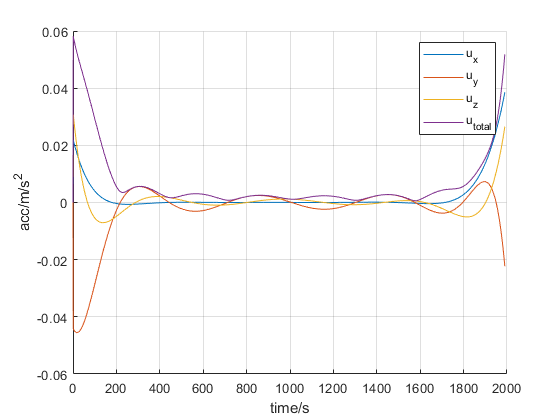

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

#### 能量最优(与间接法作对比)

@CostFuel: $\int \sqrt{u_x^2 + u_y^2 + u_z^2} \mathrm{d}t$

@CostFuel2: $\frac{1}{2} \int u_x^2 + u_y^2 + u_z^2 \mathrm{d}t$

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      91    4.387380e-03    3.176e+03    8.250e-03
    1     182    6.560675e-03    2.987e+03    2.089e-01    4.192e+00
    2     273    7.872221e-03    2.905e+03    3.000e-01    1.885e+00
    3     364    7.895451e-03    2.903e+03    3.023e-01    7.870e-02
    4     455    1.118877e-02    2.667e+03    5.627e-01    8.674e+00
    5     546    1.125195e-02    2.664e+03    5.665e-01    1.208e-01
    6     637    1.201160e-02    2.624e+03    6.090e-01    1.383e+00
    7     728    1.223527e-02    2.612e+03    6.089e-01    8.422e-01
    8     819    2.878773e-02    2.227e+03    1.286e+00    2.822e+01
    9     910    2.891488e-02    2.226e+03    1.291e+00    1.416e-01
   10    1001    2.883397e-02    2.221e+03    1.291e+00    1.169e+00
   11    

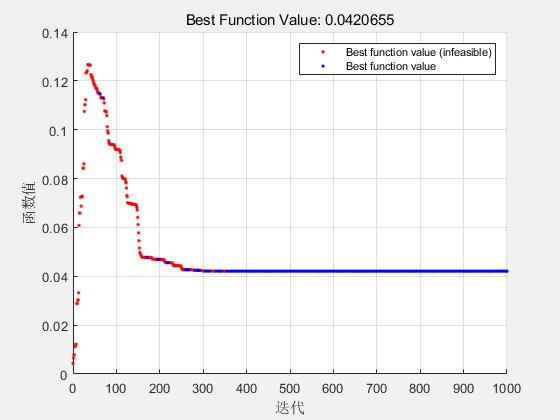


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.



args.n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [2200., 8000., 100., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
lb = [-1000, -1000, -100, -10, -10, -1, -0.01, -0.01, -0.01];
ub = [3000, 9000, 200, 10, 10, 1, 0.01, 0.01, 0.01];
[s, x_nlp, fval, exitflag, output, lambda, ct] = Gpm2(x0, xf, @CostFuel2, @CwEq, s0, lb, ub, 10, step, args);

ct

ct = 354.7528

tf_ = s(end, 1)

tf_ = 2000

J = CostFuel(s, tf_)

J = 11.3805

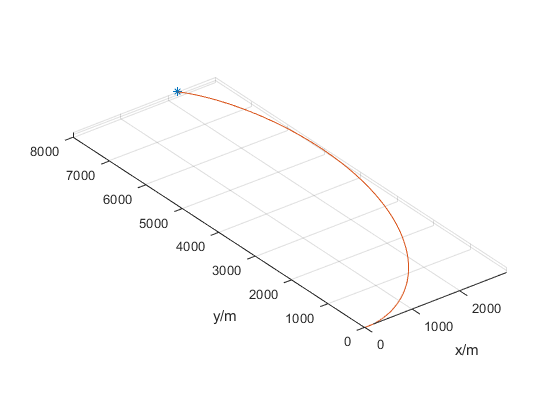

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

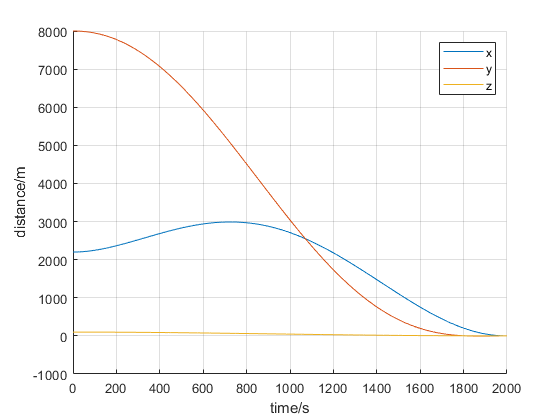

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

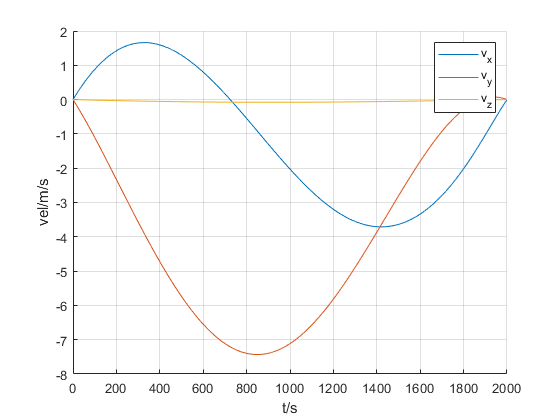

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

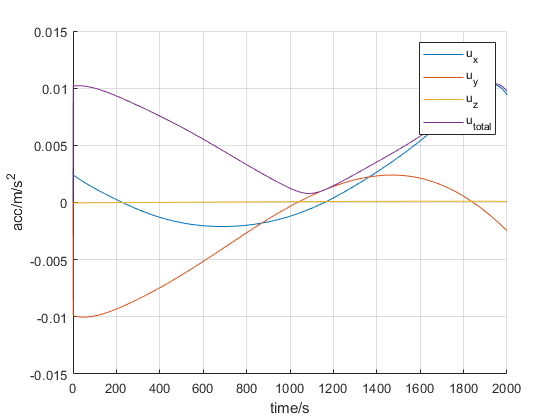

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

#### 燃料最优

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      91    7.384547e+00    3.485e+02    2.426e-02
    1     182    8.871438e+00    1.549e-03    1.260e+02    9.066e+00
    2     273    8.860031e+00    2.037e-05    2.176e+00    1.072e-01
    3     364    8.805499e+00    1.748e-04    3.209e+00    5.294e-01
    4     455    8.612456e+00    9.869e-04    6.982e+01    2.499e+00
    5     547    8.601593e+00    8.768e-04    1.097e+02    8.883e-01
    6     638    8.598032e+00    1.151e-04    1.715e+01    2.591e-01
    7     729    8.596543e+00    2.089e-05    9.553e+00    7.060e-02
    8     820    8.587431e+00    6.042e-05    4.481e+01    3.888e-01
    9     911    8.569409e+00    2.800e-05    9.946e+01    9.396e-01
   10    1002    8.541810e+00    1.190e-04    1.096e+02    1.818e+00
   11    1093    8.528341e+00    1.511e-04    1.060e+02    1.453e+00
   12    1184    8.522049e+00    1.091e-04    5

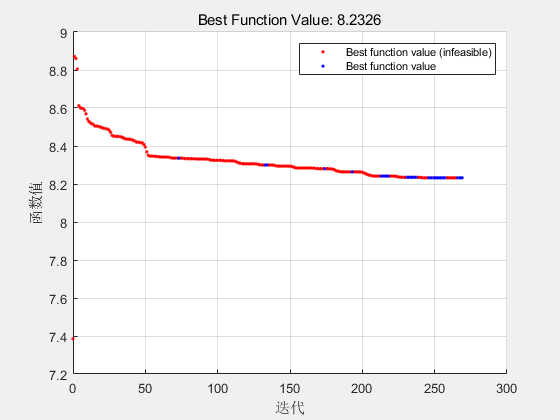


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[s, x_nlp, fval, exitflag, output, lambda, ct] = Gpm2(x0, xf, @CostFuel, @CwEq, s0, lb, ub, 10, step, args);

ct

ct = 85.9763

tf_ = s(end, 1)

tf_ = 2000

J = CostFuel(s, tf_)

J = 8.2326

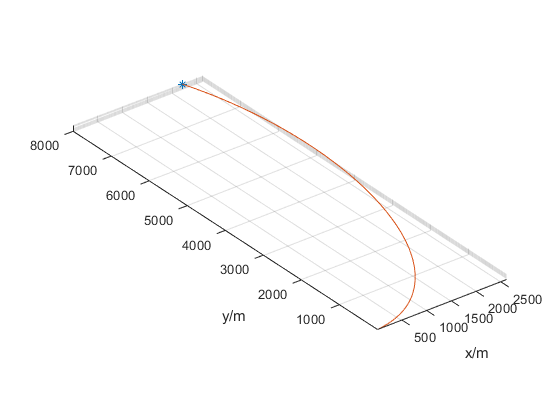

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

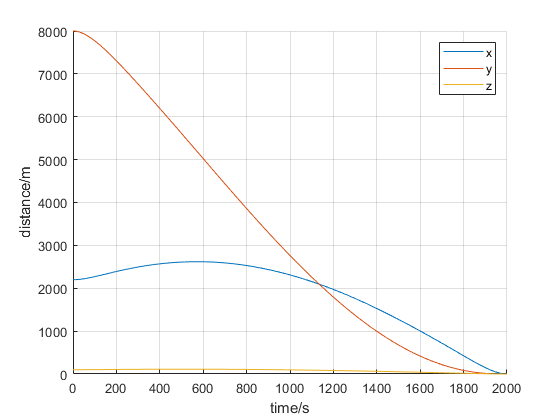

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

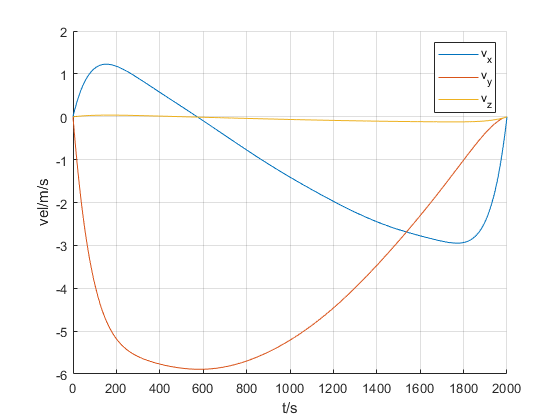

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

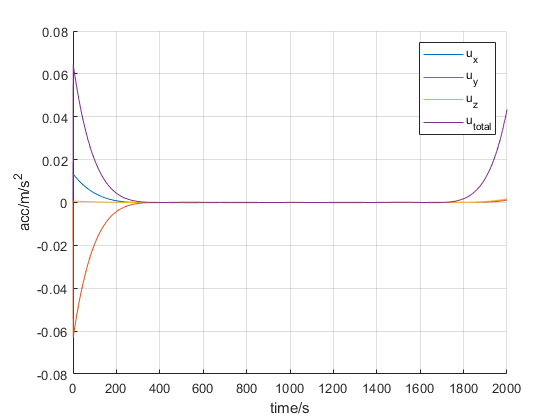

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

## 连续推力

### 间接法

tic
% [t, x] = CwIndirOpt(x0, n, tf, step, 'Riccati');
[t, x] = CwIndirOpt(x0, n, tf, step);
toc

历时 0.067808 秒。


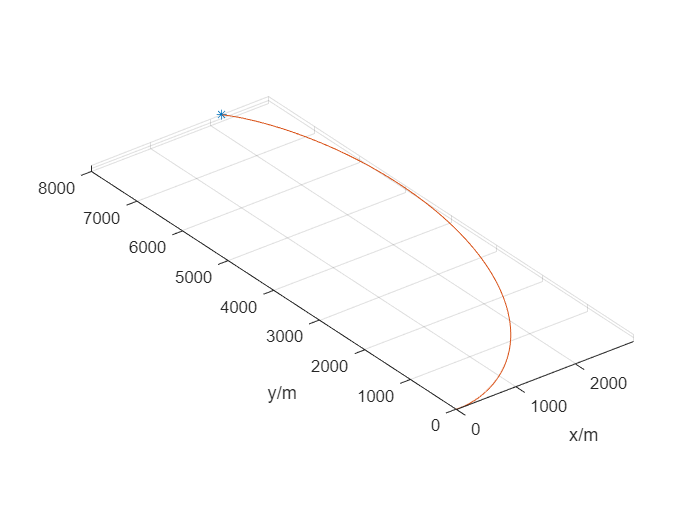

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

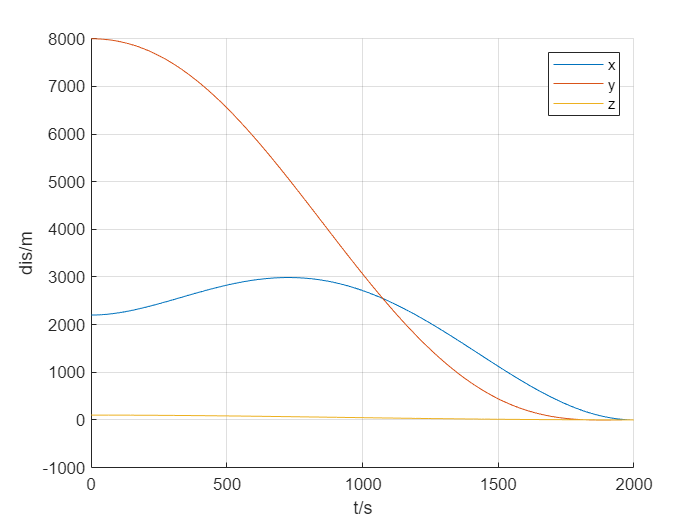

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

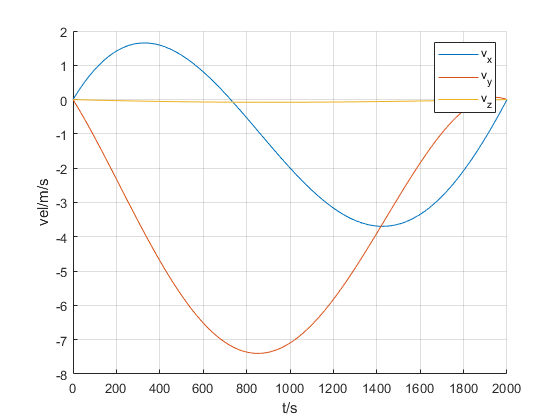

figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

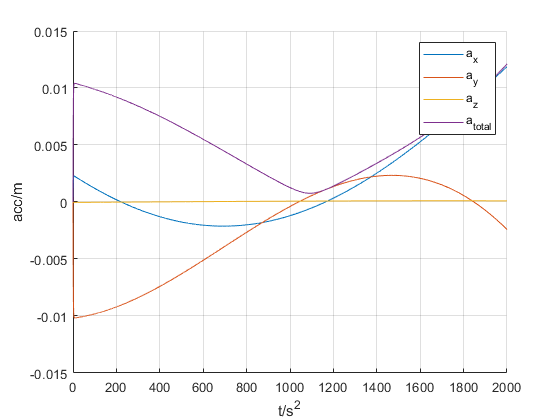

figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 11.3030

## 固定推力

x0 = [2200., 8000., 1000., 0., 0., 0.]';  % m, m/s
tf = 2000.; % s
n = 0.00111; % rad/s
tspan = 1;
f = 0.01; % m/s^2

### 间接法

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    1.800000e+03     2.315e+04     1.000e+00     0.000e+00     1.000e+00  
    1          16    1.800000e+03     1.158e+04     1.000e+00     7.747e-02     1.000e+00  
    2          24    1.799991e+03     9.421e+03     1.000e+00     4.715e-02     1.000e+00  
    3          34    1.799991e+03     7.761e+03     4.900e-01     3.132e-02     1.000e+00  
    4          42    1.798950e+03     7.410e+03     1.000e+00     1.043e+00     1.000e+00  
    5          50    1.793792e+03     2.656e+04     1.000e+00     5.158e+00     1.000e+00  
    6          58    1.793792e+03     8.903e+03     1.000e+00     7.284e-02     1.000e+00  
    7          66    1.793792e+03     7.708e+03     1.000e+00     5.862e-02  

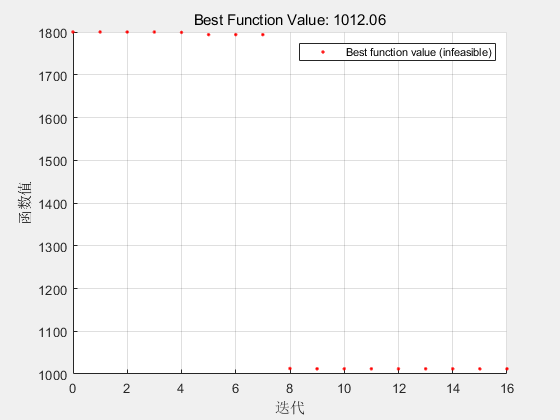


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x = 	1.0e+03 *

    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    1.0121


fval = 1.0121e+03

exitflag = -2

output = 包含以下字段的 struct :
         iterations: 16
          funcCount: 392
          algorithm: 'sqp'
            message: '↵Converged to an infeasible point.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance but constraints are not↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-09, but the relative maximum constraint↵violation, 1.651679e-01, exceeds options.ConstraintTolerance = 1.000000e-07.↵↵'
    constrviolation: 3.8233e+03
           stepsize: 7.5339e-10
       lssteplength: 5.2433e-08
      firstorderopt: 0.9998
       bestfeasible: []


tic
[t, x] = CwIndirOpt2(x0, n, f, tf, tspan);

toc

历时 6.775574 秒。


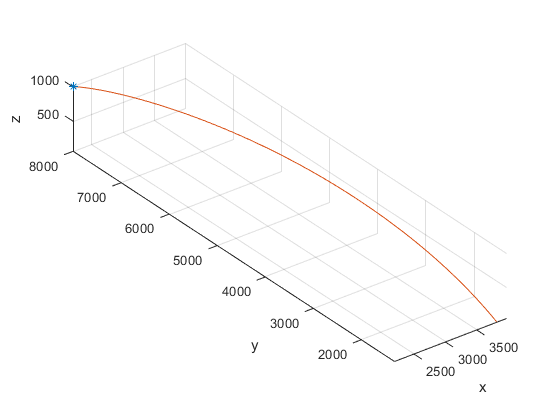

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

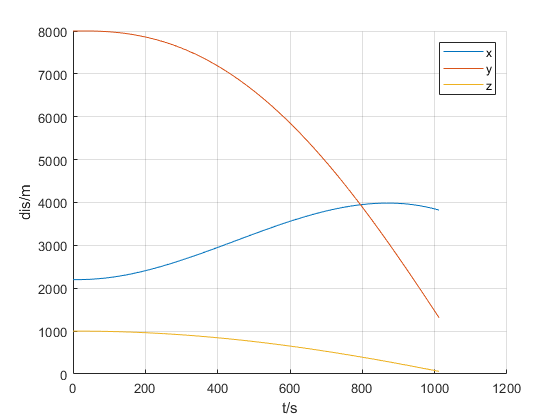

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

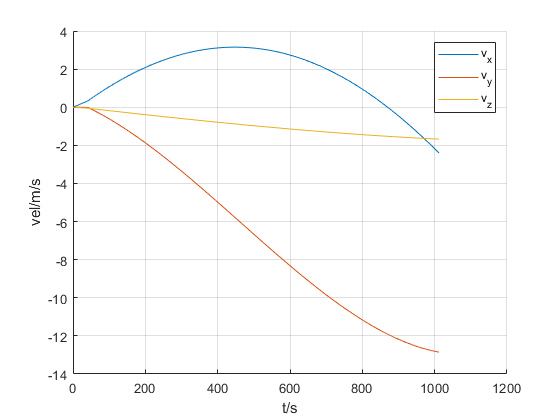

figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

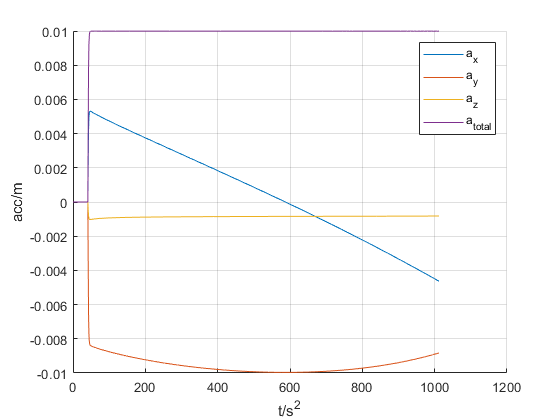

figure
hold on
plot(t, x(:, 13))
plot(t, x(:, 14))
plot(t, x(:, 15))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 13 : 15));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 19.1524